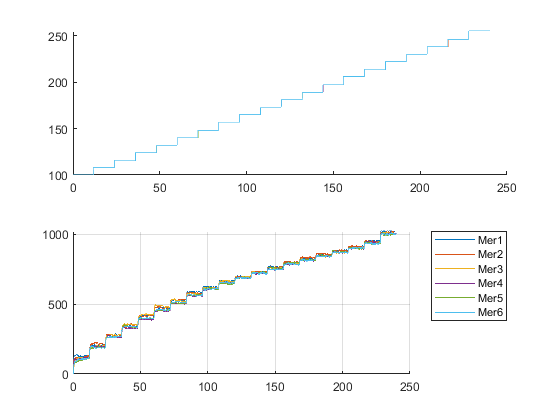

data = zeros(13541,3,6);
for i=1:12
    fileName = ['./dataRepo/allSig_log_prev_mer',num2str(i),'_up.csv'];
    dt = csvread(fileName);
    data(:,:,i) = dt(2:13542,:);
end

figure;
for i=1:6
    subplot(2,1,1);    
    name = ['Mer',num2str(i)];
    hold on;
    plot(data(:,1,i),data(:,2,i), 'DisplayName',name);
    hold off;
    subplot(2,1,2);
    hold on;
    plot(data(:,1,i),data(:,3,i),'DisplayName',name)
    hold off;
end
legend('Location',"bestoutside");
grid on;

dataSimple = zeros(6,13541);
for i=1:6    
    dataSimple(i,:) = data(:,3,i)';
end

Unable to perform assignment because the size of the left side is 1-by-13542 and the size of the right side is 1-by-13541.

dataMean = mean(dataSimple);
dataMean = dataMean';
figure;
plot(data(:,1,1),dataMean(:),'DisplayName',name)